## Introduction to Event Based Simulation

clear all

### What is `ode45`

`ode45` is a matlab feature that allows you to integrate differential equations forward in time. The basic usage looks like this:

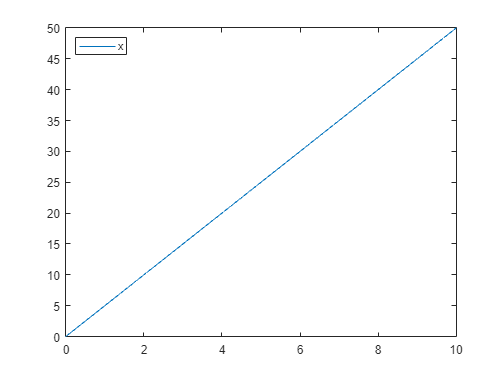

clear all
tspan = 0:.001:10;
x0 = 0;
[t,x] = ode45(@diffFunc,tspan,x0);
plot(t,x)
legend(["x"],'Location','northwest')

Some important notes:

the ode function MUST take exactly two variables: the time-vector t and the state variables x. The state variables can be represented as a vector, as in

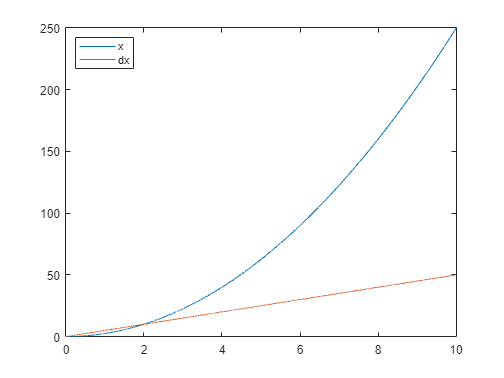

clear all
tspan = 0:.001:10;
q0 = [0;0];
[t,q] = ode45(@twoDiffFunc,tspan,q0);
plot(t,q)
legend(["x";"dx"],'Location','northwest')

This should look familiar for those of who who have taken controls; the state is represented using position and velocity, with the time-differential of position equal to the velocity and the time-differential of velocity calculated based on the applied forces (here the acceleration is simply 5). The output must be a derivative vector of the same dimension as the state vector.

You **cannot** simply add inputs or outputs to the ode function. There are clever ways to pass additional parameters, which I'll discuss later, but for now, simply accept that the function **must** take the time and state vector as inputs and output the state derivative. In both the functions defined below, time is not used, but we have to pass it as an input anyway.

### Event-Based Simulation

Event-based simulation changs the behavior of `ode45`. Specifically, it inserts a condition that `ode45` should look for in order to terminate the simulation early. Matlab is very stupid, and so you must write the code yourself to determine what should happen when this happens. In general, you will either want to restart simulating with new initial conditions, or you will want to terminate.

You may ask yourself, "why do we need to do this anyway?" and the answer is that `ode45` is not for differential equations with hybrid states. Let's look at what happens when we try to implement hybrid states in `ode45` in a naive way using if/else statements, zooming in on the problem areas.

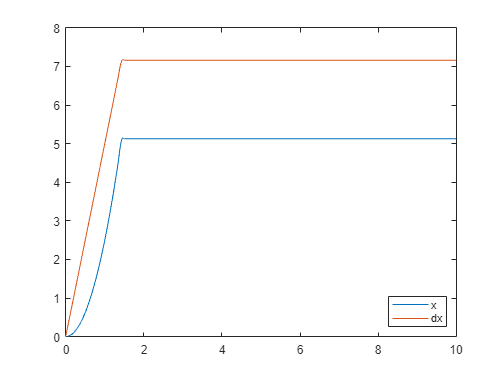

clear all
tspan = 0:.001:10;
q0 = [0;0];
[t,q] = ode45(@twoDiffFuncStates,tspan,q0);
plot(t,q)
legend(["x";"dx"],'Location','southeast')

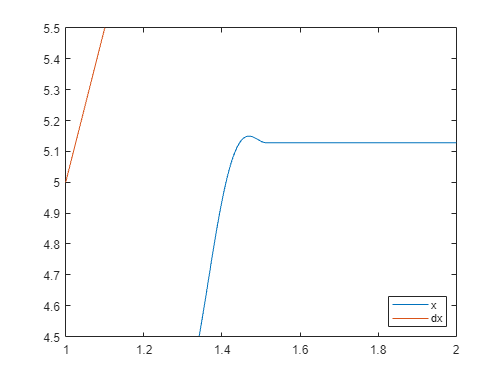

plot(t,q)
legend(["x";"dx"],'Location','southeast')
xlim([1,2]);
ylim([4.5,5.5]);

As you can see, around the transition point, there's a small "hump" in the system behavior, and also the velocity is represented in a weird and insane way. This is because ode45 is trying to "smooth" the function behavior - it uses a runge-kutta algorthm, which interpolates. We don't want this to happen around hybrid state transitions; instead, we want *accurate* behavior all the way up to impact instead.

In order to achieve this, we do not allow the system behavior to switch until we actually hit a new hybrid state, and use a guard to detect when this happens. Let's look at how we might implement that.

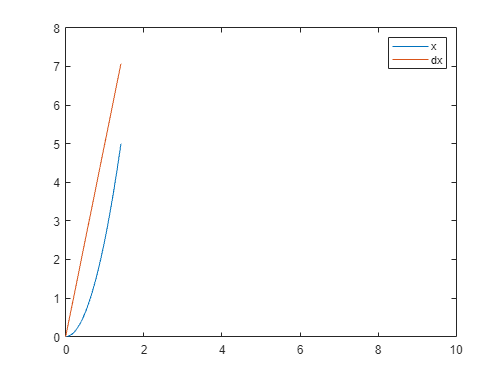

clear all
tspan = 0:.001:10;
q0 = [0;0];
optionSet = odeset('Events', @guardFunc);
[t,q] = ode45(@twoDiffFunc,tspan,q0,optionSet);
plot(t,q)
xlim([0,10])
legend(["x";"dx"],'Location','northeast')

As you can see, we have no hump here!

Digressing for a moment into the anatomy of the guard function; let us note a few things

First, the guard function produces three outputs and takes inputs of time and state. Like the ode function, these inputs and outputs are fixed and cannot be changed.

Second, the guards have the following data structure: first, there is an entry in `constraintFcns` that should trigger the guard when its sign changes. Second, there is a an entry in `isterminal` that determines whether this event should terminate the simulation - for this class, our answer is almost always "yes," so this should almost always be "1." Third, there is an entry in `direction` that determines whether the guard will trigger when the sign changes from positive to negative, negative to positive, or both. "0," for "either direction," is usually a safe bet, but there are times when you won't want that.

Third, and to reiterate what I noted above: the sign of the guard function MUST CHANGE. For this example, we used `q-5`, which looks like this:

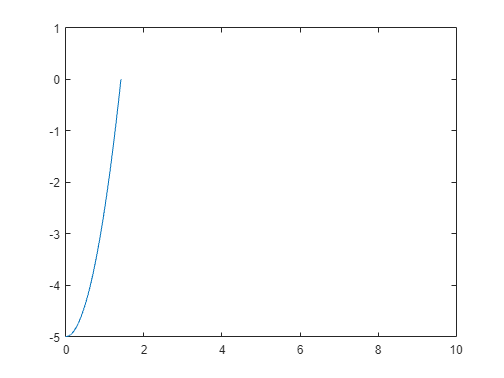

plot(t,q(:,1)-5)
xlim([0,10])

If we were to try to use a different guard function which reaches zero but whose sign never changes, such as `(q-5)^2`, but which still reaches zero at the right place...

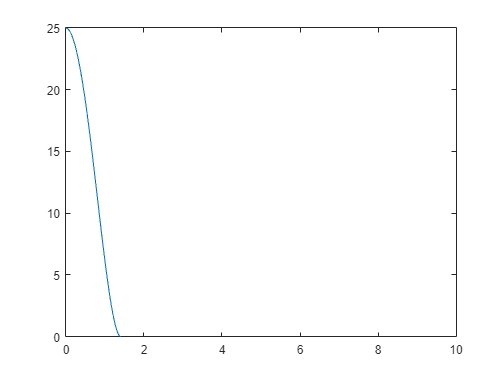

plot(t,(q(:,1)-5).^2)
xlim([0,10])

... we would see...

clear all
tspan = 0:.001:10;
q0 = [0;0];
optionSet = odeset('Events', @badGuardFunc);
[t,q] = ode45(@twoDiffFunc,tspan,q0,optionSet);
plot(t,q)
legend(["x";"dx"],'Location','northwest')

... no termination of the simulation, since the sign of the guard function never changes!

The lesson here is important: **make sure the sign of your guard function actually changes when you expect the system state to change**!

### Restarting Simulation

OK, so now we know how to make the simulation stop when we want it to, the question is now how to keep on running. In this case, because we know what should happen after impact, we can just keep going, manually calculating the new ICs post-transition, as below:

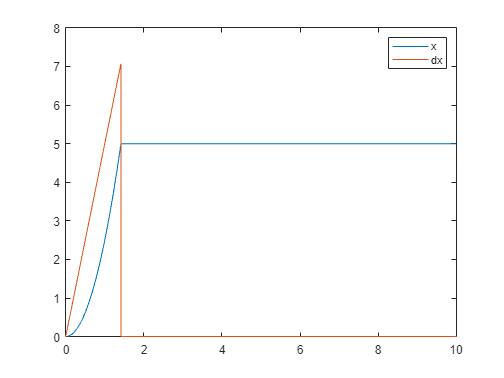

clear all
tspan = 0:.001:10;
q0 = [0;0];
optionSet = odeset('Events', @guardFunc);
%sim 1
[t1,q1] = ode45(@twoDiffFunc,tspan,q0,optionSet);
%new zero-velocity IC
q0 = [q1(end,1);0];
%start from the end of previous sim time
tspan = t1(end):.001:10;
%sim 2
[t2,q2] = ode45(@twoDiffFuncStandstill,tspan,q0,optionSet);
%combine time and state vectors
t = [t1;t2];
q = [q1;q2];

plot(t,q)
legend(["x";"dx"],'Location','northeast')

Ideally, though, you'd want to track the system's hybrid state and transition automatically. The homework goes down that road, wrapping the `ode45` in a while loop and using that while loop to do this. In principle, though, the steps are as follows:

1) detect simulation termination

2) detect which new state you have entered - this must be a separate function, the guard function can't return this

3) determine new initial conditions

4) restart simulation using the correct dynamics in your new hybrid state post-transition

5) concatenate all the individual hybrid state simulations together to get the full-time system behavior

The complicated parts of *this* are the subject of these last few lectures, and aren't in the scope of this tutorial.

### Passing More Parameters (aka Cheating)

Around now you may be realizing that if we could pass hybrid state information to the ode functions, guard functions, and more, we'd be very very happy about that. Unfortunately, as structured, Matlab makes that hard to figure out how to do.

Luckily, though, it is not impossible.

In order to do this, we need to take advantage of Matlab's anonymous functions. Anonymous functions are defined for a set of inputs and will only ever return single-line outputs. They also have access to variables int he scope where that function is defined. This might look like:

clear all
y = 5;
f = @(x) x+y

f = function_handle with value:
    @(x)x+y


f(5)

ans = 10

y = 10;
f(5)

ans = 10

Let me unpack this a little.

`@(x)` means, "this is an anonymous function that takes the variable `x`." This is followed by the operation that yields the return of the function. If this operation uses a variable in the current environemnt which is *not* passed as an input to the function, the value is and becomes static when the function is defined. We then take this function and put it in `f`. We can then call `f` and have it return f(x).

How does this help us?

Well, anonymous functions can be used to smuggle other parameters into, say, a guard function. We can let the guard and ode functions be anonymous functions that *then* call the functions that we write to accept additional parameters, like so:

clear all
tspan = 0:.001:10;
q0 = [0;0];
state = 1;
%sim 1
optionSet = odeset('Events', @(t,q) guardFuncPlus(t,q,state));
[t1,q1] = ode45(@(t,q) twoDiffFuncPlus(t,q,state),tspan,q0,optionSet);
state = 2

state = 2

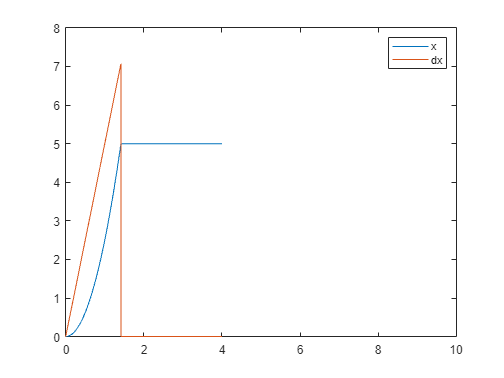

%new zero-velocity IC
q0 = [q1(end,1);0];
%start from the end of previous sim time
tspan = t1(end):.001:10;
%sim 2
optionSet = odeset('Events', @(t,q) guardFuncPlus(t,q,state));
[t2,q2] = ode45(@(t,q) twoDiffFuncPlus(t,q,state),tspan,q0,optionSet);
%combine time and state vectors
t = [t1;t2];
q = [q1;q2];

plot(t,q)
xlim([0,10])
legend(["x";"dx"],'Location','northeast')

Note something important here: **the value of state is read when the anonymous function is *****created*****, not continuously**. This is why we have to re-initialize the option set with `guardFuncPlus` after we change state; if we didn't, it would not apply the t=4 guard condition.

To recap: when we use these anonymous function, we create a function that takes `t` and `q`, plus some other parameters - like `state` - that are read when the function is initialized. Otherwise, these functions work exactly like normal ode and guard functions. We still cannot augment the *returns* of those functions - and if we could, those augmented results would not be saved anywhere.

### Functions Used In This Tutorial

function dx = diffFunc(t,x)
    dx = 5;
end

function dq = twoDiffFunc(t,q)
    x = q(1);
    dx = q(2);

    ddx = 5;
    dq = [dx;ddx];
end

function dq = twoDiffFuncStates(t,q)
    x = q(1);
    
    if x < 5
        dx = q(2);
        ddx = 5;
    else
        dx = 0;
        ddx = 0;
    end

    dq = [dx;ddx];
end

function dq = twoDiffFuncStandstill(t,q)
    x = q(1);
    dx = q(2);

    dq = [dx;0];
end

function dq = twoDiffFuncPlus(t,q,state)
    x = q(1);
    dx = q(2);
    
    if state == 1
        ddx = 5;
    else
        ddx = 0;
    end

    dq = [dx;ddx];
end

function [constraintFcns,isterminal,direction] = guardFunc(t,q)
    constraintFcns = [];
    isterminal = [];
    direction = [];

    x = q(1);
    dx = q(2);

    constraintFcns = [constraintFcns,x - 5];
    isterminal = [isterminal, 1];
    direction = [direction,0];
end

function [constraintFcns,isterminal,direction] = badGuardFunc(t,q)
    constraintFcns = [];
    isterminal = [];
    direction = [];

    x = q(1);
    dx = q(2);

    constraintFcns = [constraintFcns,(x - 5)^2];
    isterminal = [isterminal, 1];
    direction = [direction,0];
end

function [constraintFcns,isterminal,direction] = guardFuncPlus(t,q,state)
    constraintFcns = [];
    isterminal = [];
    direction = [];

    x = q(1);
    dx = q(2);

    if state == 1
        constraintFcns = [constraintFcns,x - 5];
        isterminal = [isterminal, 1];
        direction = [direction,0];
    else
        constraintFcns = [constraintFcns,t-4];
        isterminal = [isterminal, 1];
        direction = [direction,0];
    end
end